# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 2: Threshold & Segmemtation 

# Date: 01/12/2022

clf

% Original RGB images
    % textured images
    ashy_Larry = imread("Ashy_Larry.jpeg");
    rocky_Road = imread("Rocky_Road.jpeg");
    % non-textured images
    love = imread("love.jpeg");
    unique = imread('unique.jpeg');
% Grayscale of Images
    % textured images
        ashy_gray = rgb2gray(ashy_Larry);
        rocky_gray = rgb2gray(rocky_Road);
        % non-textured images
        love_gray = rgb2gray(love);
        unique_gray = rgb2gray(unique);

% Execute the Otsu function for each grayscale texture and non-texture
% image then test the threshold value acquired from the function with
% matlabs internal function

% Texture image 1
ashyHist = imhist(ashy_gray);
[ashyQ, ~, ~] = OtsuMethod(ashyHist)

ashyQ = 146

[counts, ~] = imhist(ashy_gray);
[~, EM] = otsuthresh(counts)

EM = 0.8024

EM = EM*100*256/100

EM = 205.4214

algoTest(ashy_gray, ashyQ)

value = 145.5686

ans = "0.29634%"

% Texture image 2
rockyHist = imhist(rocky_gray);
[rockyQ, ~, ~] = OtsuMethod(rockyHist)

rockyQ = 62

[counts, ~] = imhist(rocky_gray);
[~, EM] = otsuthresh(counts)

EM = 0.6995

EM = EM*100*256/100

EM = 179.0761

algoTest(rocky_gray, rockyQ)

value = 61.2392

ans = "1.2423%"

% Non-Texture image 1
loveHist = imhist(love_gray);
[loveQ, ~, ~] = OtsuMethod(loveHist)

loveQ = 118

[counts, ~] = imhist(love_gray);
[~, EM] = otsuthresh(counts)

EM = 0.7136

EM = EM*100*256/100

EM = 182.6723

algoTest(love_gray, loveQ)

value = 117.4588

ans = "0.46074%"

% Non-Texture image 2
uniqueHist = imhist(unique_gray);
[uniqueQ, ~, ~] = OtsuMethod(uniqueHist)

uniqueQ = 138

[counts, ~] = imhist(unique_gray);
[~, EM] = otsuthresh(counts)

EM = 0.8696

EM = EM*100*256/100

EM = 222.6116

algoTest(unique_gray, uniqueQ)

value = 137.5373

ans = "0.33645%"

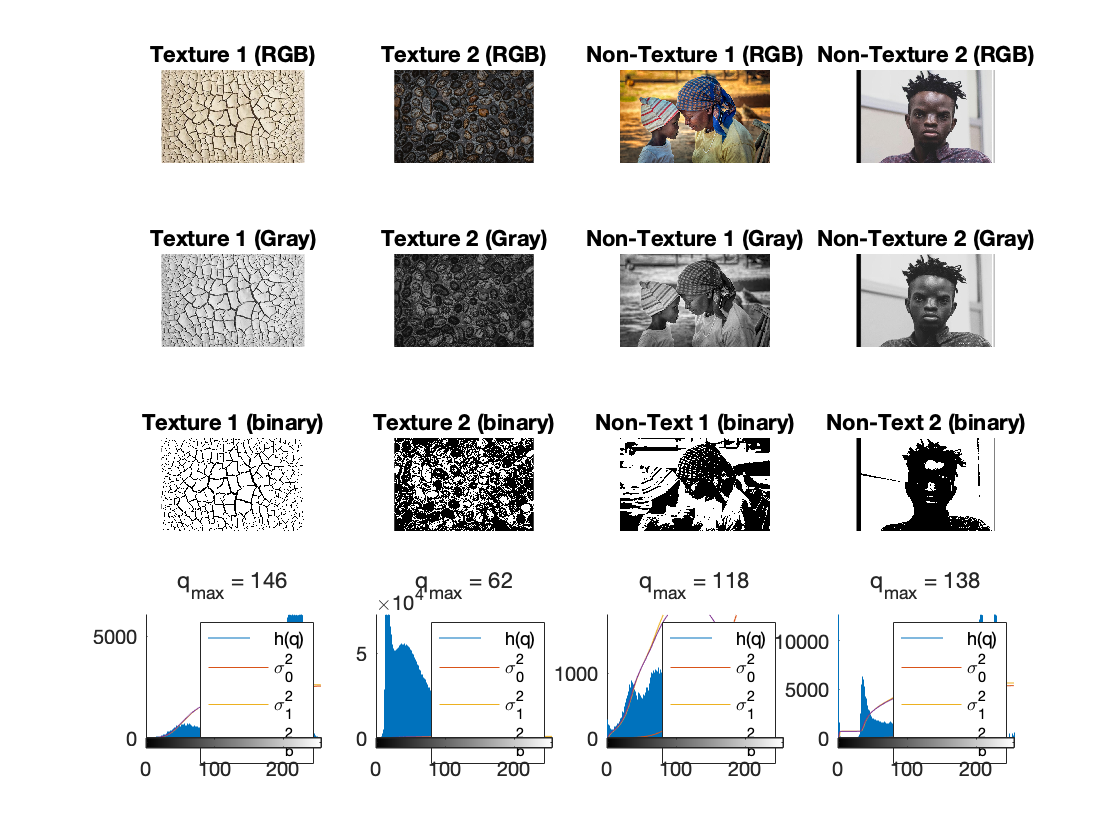

% Create subplots of images
        % Original images
        subplot(4,4,1), imshow(ashy_Larry), title('Texture 1 (RGB)')
        subplot(4,4,2), imshow(rocky_Road), title('Texture 2 (RGB)')
        subplot(4,4,3), imshow(love), title('Non-Texture 1 (RGB)')
        subplot(4,4,4), imshow(unique), title('Non-Texture 2 (RGB)')
        % Gray images
        subplot(4,4,5), imshow(ashy_gray), title('Texture 1 (Gray)')
        subplot(4,4,6), imshow(rocky_gray), title("Texture 2 (Gray)")
        subplot(4,4,7), imshow(love_gray), title("Non-Texture 1 (Gray)")
        subplot(4,4,8), imshow(unique_gray), title("Non-Texture 2 (Gray)")
        % Binarized image with Otsu threshold
        subplot(4,4,9), imshow(imbinarize(ashy_gray, ashyQ/256)), title("Texture 1 (binary)"),...
            xlabel("q_{max} = " + ashyQ);
        subplot(4,4,10), imshow(imbinarize(rocky_gray, rockyQ/256)), title("Texture 2 (binary)"),...
             xlabel("q_{max} = " + rockyQ);
        subplot(4,4,11), imshow(imbinarize(love_gray, loveQ/256)), title("Non-Text 1 (binary)"),...
             xlabel("q_{max} = " + loveQ);
        subplot(4,4,12), imshow(imbinarize(unique_gray, uniqueQ/256)), title("Non-Text 2 (binary)"),...
             xlabel("q_{max} = " + uniqueQ);
        % histogram of original image, background variance, foreground
        % variance, and the variance between foreground and background
        subplot(4,4,13), hold on, imhist(ashy_gray),
            plot(backgroundVariance(ashyHist)),
            plot(foregroundVariance(ashyHist)),
            [~, ~, sigmabetween] = OtsuMethod(ashyHist);
            plot(sigmabetween),
            legend('h(q)', '\sigma_{0}^{2}',...
            '\sigma_{1}^{2}', '\sigma_{b}^{2}'), hold off
        subplot(4,4,14), hold on, imhist(rocky_gray),...
            plot(backgroundVariance(rockyHist)),
            plot(foregroundVariance(rockyHist)),
            [~, ~, sigmabetween] = OtsuMethod(rockyHist);
            plot(sigmabetween),
            legend('h(q)', '\sigma_{0}^{2}',...
            '\sigma_{1}^{2}', '\sigma_{b}^{2}'), hold off
        subplot(4,4,15), hold on, imhist(love_gray),...
            plot(backgroundVariance(loveHist)),
            plot(foregroundVariance(loveHist)),
            [~, ~, sigmabetween] = OtsuMethod(loveHist);
            plot(sigmabetween),
            legend('h(q)', '\sigma_{0}^{2}',...
            '\sigma_{1}^{2}', '\sigma_{b}^{2}'), hold off
        subplot(4,4,16), hold on, imhist(unique_gray),...
            plot(backgroundVariance(uniqueHist)),
            plot(foregroundVariance(uniqueHist)),
            [~, ~, sigmabetween] = OtsuMethod(uniqueHist);
            plot(sigmabetween),
            legend('h(q)', '\sigma_{0}^{2}',...
            '\sigma_{1}^{2}', '\sigma_{b}^{2}'), hold off

This algorithm is very powerful for finding the optimal threshold value for an image.  Since the mean is precalcuated, the Otsu method passes over the grayscale histogram 3 times. 0(K) makes the Otsu method very fast compared to other algorithms mentioned in the literature. Knowing the threshold value of an image allows us to segment the foreground from the background. Segmentation of the two backgrounds aids in computer vision by distinguishes objects in a picture. 

function [mu0, mu1, N, K, n1Vec] = MakeMeanTable(grayscaleHistogram)
    K = size(grayscaleHistogram,1);
    % Create Mean Table of the Histogram
    n0 = 0;
    s0 = 0; % Sum of pixel values
    % Tabulate background means mu0(q)
    % Create a vector to store the means of the background
    mu0 = zeros(256, 1);
    for q = 1:K
        for r = 1:size(grayscaleHistogram,2)
        n0 = n0 + grayscaleHistogram(q,r);
        s0 = s0 + q*grayscaleHistogram(q,r);
            if n0 > 0
                mu0(q,r) = s0/n0;
            else
                mu0(q,r) = -1;
            end        
        end
    end
    N = n0;
    % Tabulate foreground means
    n1 = 0;
    n1Vec = zeros(256,1);
    s1 = 0;
    % Create a vector to store the means of the foreground
    mu1 = zeros(256, 1);
    for q = K-1:-1:1
        for r = 1:size(grayscaleHistogram,2)
            n1 = n1 + grayscaleHistogram(q+1,r);
            n1Vec(q,r) = n1;
            s1 = s1 + (q+1)*grayscaleHistogram(q+1,r);
            if n1 > 0
                mu1(q,r) = s1/n1;
            else
                mu1(q,r) = -1;
            end
        end
    end
end

% Write a function to execute the Otsu method on the texture and
function [qMax, sigmaBetweenMax, sigmaBetween] = OtsuMethod(grayscaleHistogram)
    % This function takes as its input a grayscale histogram and returns the
    % optimal threshold value or -1 if no threshold is found
    % MakeMean Tables(h)
    [mu0, mu1, N, K, ~] = MakeMeanTable(grayscaleHistogram); % When there are multiple arguments returned make sure to enclose them in brackets
    sigmaBetween = zeros(256,1);
    sigmaBetweenMax = 0; % Set the maximum between class variance to 0
    qMax = -1; % Set the max threshold value to -1
    n0 = 0;
    % Examine all possible threshold values q
    for q = 1:K-1
        for r = 1:size(grayscaleHistogram,2)
            % Sum up the number of pixels
            n0 = n0 + grayscaleHistogram(q,r);
            n1 = N - n0;
            if n0 > 0 && n1 > 0
                sigmaBetween(q,r) = (1/(N.^2))*n0*n1*(mu0(q,r) - mu1(q,r))^2;
                % Maximize sigma^2_b
                if sigmaBetween(q,r) > sigmaBetweenMax
                    sigmaBetweenMax = sigmaBetween(q,r);
                    qMax = q;
                end
            end
        end
    end
end

% Function to check error
function [error] = algoTest(grayscaleHistogram, experimentalValue)
[counts, ~] = imhist(grayscaleHistogram);
value = otsuthresh(counts);
value = (value*100*256)/100
% The value is normalized, convert it to an indexed value
error = (abs(value-experimentalValue)/value)*100+"%";
end

% Function to calculate background variance
function backVec = backgroundVariance(grayscaleHistogram)
    n0 = 0;
    backVar = 0;
    backVec = zeros(256, 1);
    [mu0, ~, ~, ~, ~] = MakeMeanTable(grayscaleHistogram);
    for i = 1:256
        for j = 1:size(grayscaleHistogram,2)
            n0 = n0 + grayscaleHistogram(i,j);
            backVar = backVar + (i - mu0(i,j))^2*grayscaleHistogram(i,j);
            backVec(i+1,j) = backVar;
        end
    end
    backVec = (1/n0)*backVec;
end

% Function to calculate foreground variance
function  foreVec = foregroundVariance(grayscaleHistogram) 
    n0 = 0;
    foreVar = 0;
    foreVec = zeros(256, 1);
    [~, mu1, ~, ~, ~] = MakeMeanTable(grayscaleHistogram);
    for i = 1:256
        for j = 1:size(grayscaleHistogram,2)
            n0 = n0 + grayscaleHistogram(i,j);
            foreVar = foreVar + (i - mu1(i,j))^2*grayscaleHistogram(i,j);
            foreVec(i+1,j) = foreVar;
        end
    end
    foreVec = (1/n0)*foreVec;
end

% Function to calculate within-class variance
function  withinVec = withinClassVariance(grayscaleHistogram) 
foreVec = foregroundVariance(grayscaleHistogram);
backVec = backgroundVariance(grayscaleHistogram);
[~, ~, N, ~, n1Vec] = MakeMeanTable(grayscaleHistogram);
    n0 = 0;
    withinVar = 0;
    withinVec = zeros(256, 1);
    for i = 1:256
        for j = 1:size(grayscaleHistogram,2)
            n0 = n0 + grayscaleHistogram(i,j);
            withinVar = withinVar + (i*backVec(i,j) + n1Vec(i,j)*foreVec(i,j));
            withinVec(i,j) = withinVar;
        end
    end
    withinVec = (1/N)*withinVec;
end

% function to calculate goodness
function eta = Goodness(grayscaleHistogram)
[qMax, ~, sigmabetween] = OtsuMethod(grayscaleHistogram);
withinVec = withinClassVariance(grayscaleHistogram);
sigmaTotal = withinVec+sigmabetween;
eta = sigmabetween(qMax,1)/sigmaTotal(qMax,1);
end